clear all

## Defining variables

syms m1 g m2 M L1 L2 x dx 
m1 = 100;
m2 = 100;
M = 1000;
L1 = 20;
L2 = 10;
g = 9.81;
tspan = 0:0.1:100;

% Initial conditions
X0 = [0 0 -deg2rad(20) 0 deg2rad(30) 0];

## Linearized Model

A = [0 1 0 0 0 0; 0 0 -m1*g/M 0 -m2*g/M 0; 0 0 0 1 0 0; 0 0 -((M*g)+(m1*g))/(M*L1) 0 -g*m2/(M*L1) 0; 0 0 0 0 0 1; 0 0 -m1*g/(M*L2) 0 -((M*g)+(m2*g))/(M*L2) 0];
B = [0; 1/M; 0; 1/(L1*M); 0; 1/(L2*M)];
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0];
D = [1;0;0];
Rank = rank([B A*B (A^2)*B (A^3)*B (A^4)*B (A^5)*B])

Rank = 6

## LQR Controller

Q = [1/12 0 0 0 0 0; 0 1/(12*0.1) 0 0 0 0; 0 0 1/(8*0.2^2) 0 0 0; 0 0 0 1/(12*0.01^2) 0 0; 0 0 0 0 1/(8*0.2^2) 0; 0 0 0 0 0 1/(12*0.01^2)];
R = 0.00001;
[K,S,P] = lqr(A,B,Q,R);
sys = ss(A-B*K,B,C,D);
% step(sys,200);
eigenvalues_after_LQR = eig(A-B*K)

eigenvalues_after_LQR =   -0.4582 + 0.8685i
  -0.4582 - 0.8685i
  -0.2314 + 0.1631i
  -0.2314 - 0.1631i
  -0.1215 + 0.7440i
  -0.1215 - 0.7440i


## Linear model controlled response

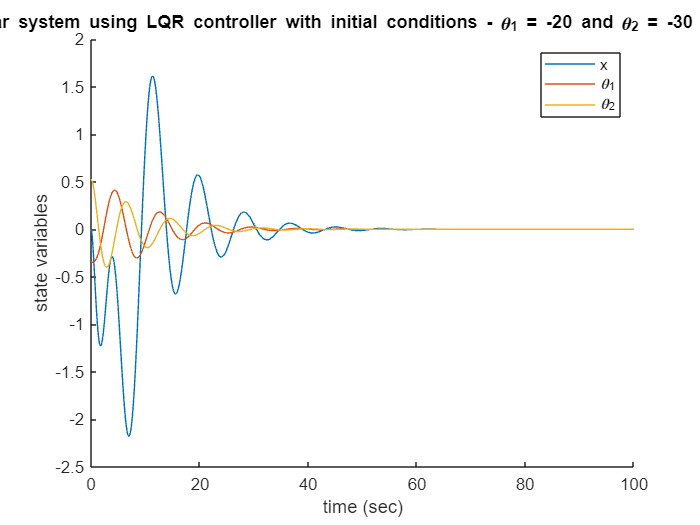

[t,x_linear] = ode45(@(t,X)linear(t,X,-K*X),tspan,X0);
figure(1);
hold on
plot(t,x_linear(:,1))
plot(t,x_linear(:,3))
plot(t,x_linear(:,5))
ylabel('state variables')
xlabel('time (sec)')
title('Linear system using LQR controller with initial conditions - \theta_1 = -20 and \theta_2 = -30 degrees')
legend('x','\theta_1','\theta_2')

## Non-Linear model controlled response

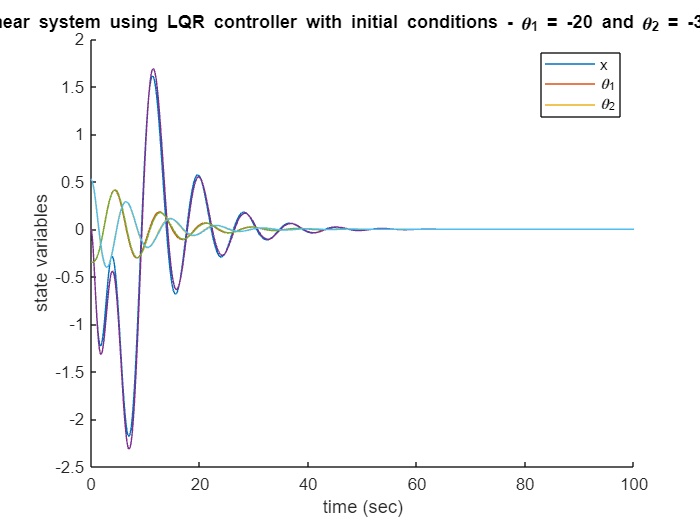

[t,x_nlinear] = ode45(@(t,X)nonLinear(t,X,-K*X),tspan,X0);
figure(2);
hold on
plot(t,x_nlinear(:,1))
plot(t,x_nlinear(:,3))
plot(t,x_nlinear(:,5))
ylabel('state variables')
xlabel('time (sec)')
title('Non-Linear system using LQR controller with initial conditions - \theta_1 = -20 and \theta_2 = -30 degrees')
legend('x','\theta_1','\theta_2')

## Defining linear model system

function dX = linear(t,X,U)
m1 = 100; m2 = 100; M = 1000; L1 = 20; L2 = 10; g = 9.81;

A = [0 1 0 0 0 0; 0 0 -m1*g/M 0 -m2*g/M 0; 0 0 0 1 0 0; 0 0 -((M*g)+(m1*g))/(M*L1) 0 -g*m2/(M*L1) 0; 0 0 0 0 0 1; 0 0 -m1*g/(M*L2) 0 -((M*g)+(m2*g))/(M*L2) 0];
B = [0; 1/M; 0; 1/(L1*M); 0; 1/(L2*M)];
dX = A*X + B*U;
end

## Defining non-linear model system

function dX = nonLinear(t,X,F)
m1 = 100; m2 = 100; M = 1000; L1 = 20; L2 = 10; g = 9.81;
x = X(1);
dx = X(2);
t1 = X(3);
dt1 = X(4);
t2 = X(5);
dt2 = X(6);
dX=zeros(6,1);
dX(1) = dx;
dX(2) = (F-((m1*sin(t1)*cos(t1))+(m2*sin(t2)*cos(t2)))*g - (L1*m1*(dX(3)^2)*sin(t1)) - (L2*m2*(dX(5)^2)*sin(t2)))/(m1+m2+M-(m1*(cos(t1)^2))-(m2*(cos(t2)^2)));
dX(3) = dt1;
dX(4) = (cos(t1)*dX(2)-g*sin(t1))/L1;
dX(5) = dt2;
dX(6) = (cos(t2)*dX(2)-g*sin(t2))/L2;
end